%import toolboxes
addpath( genpath('C:\Program Files\MATLAB\R2023b\toolbox\ft4topo')); % Datenpfad
addpath(genpath('C:\Program Files\MATLAB\R2023b\toolbox\NoiseTools')); % Datenpfad
addpath( genpath('C:\Program Files\MATLAB\R2023b\toolbox\scripts_duerschmid')); % Datenpfad

%DATA
FifFile = {'D:\Dokumente\THU\Thesis\Bachelor\pre_filtered_data.fif'}

FifFile = 1×1 cell array
    {'D:\Dokumente\THU\Thesis\Bachelor\rest_18\cogfat_rest_18_ok24-rall_mci_sss_ds2.fif'}


% Read the header
header = ft_read_header(FifFile);

	306 MEG channel locations transformed
Reading D:\Dokumente\THU\Thesis\Bachelor\rest_18\cogfat_rest_18_ok24-rall_mci_sss_ds2.fif ...
Opening raw data file D:\Dokumente\THU\Thesis\Bachelor\rest_18\cogfat_rest_18_ok24-rall_mci_sss_ds2.fif...
	Range : 25000 ... 2135999  =     50.000 ...  4271.998 secs
Ready.


% Display the channel labels
disp('Channel labels:');

Channel labels:


disp(header.label);

    {'EOG002' }
    {'ECG003' }
    {'BIO004' }
    {'BIO005' }
    {'EEG001' }
    {'EEG002' }
    {'EEG003' }
    {'EEG004' }
    {'EEG005' }
    {'EEG006' }
    {'EEG007' }
    {'EEG008' }
    {'EEG009' }
    {'EEG010' }
    {'EEG011' }
    {'EEG012' }
    {'EEG013' }
    {'EEG014' }
    {'EEG015' }
    {'EEG016' }
    {'EEG017' }
    {'EEG018' }
    {'EEG019' }
    {'EEG020' }
    {'EEG021' }
    {'EEG022' }
    {'EEG023' }
    {'EEG024' }
    {'EEG025' }
    {'EEG026' }
    {'EEG027' }
    {'EEG028' }
    {'EEG029' }
    {'EEG030' }
    {'MEG0111'}
    {'MEG0112'}
    {'MEG0113'}
    {'MEG0121'}
    {'MEG0122'}
    {'MEG0123'}
    {'MEG0131'}
    {'MEG0132'}
    {'MEG0133'}
    {'MEG0141'}
    {'MEG0142'}
    {'MEG0143'}
    {'MEG0211'}
    {'MEG0212'}
    {'MEG0213'}
    {'MEG0221'}
    {'MEG0222'}
    {'MEG0223'}
    {'MEG0231'}
    {'MEG0232'}
    {'MEG0233'}
    {'MEG0241'}
    {'MEG0242'}
    {'MEG0243'}
    {'MEG0311'}
    {'MEG0312'}
    {'MEG0313'}
    {'MEG0321'}
    {'ME

addpath(genpath('C:\Program Files\MATLAB\R2023b\toolbox\fieldtrip-20180701'));  % Adds FieldTrip to the MATLAB path
ft_defaults;  % Initializes FieldTrip defaults

%initialize data structures
%meg.data = []; % hier legen wir eine structure an, in die die Daten geschrieben werden
%eog.data = []; % hier legen wir eine structure an, in die die Daten geschrieben werden
trigchan = [];
eeg.data = [];
%ecg.data = [];

% Read header and recording information
meg.header = ft_read_header(FifFile);

	306 MEG channel locations transformed
Reading D:\Dokumente\THU\Thesis\Bachelor\rest_18\cogfat_rest_18_ok24-rall_mci_sss_ds2.fif ...
Opening raw data file D:\Dokumente\THU\Thesis\Bachelor\rest_18\cogfat_rest_18_ok24-rall_mci_sss_ds2.fif...
	Range : 25000 ... 2135999  =     50.000 ...  4271.998 secs
Ready.



%eog.srate = meg.header.Fs;
%eeg.srate = meg.srate;
%meg.channels = strmatch('MEG',meg.header.label); 
%meg.channels = meg.channels(1:3:end); % Assuming you want every third channel
%eog.channels = strmatch('EOG', meg.header.label);
%ecg.channels = strmatch('BIO004', meg.header.label);
%breath.channels = strmatch('BIO005', meg.header.label);
eeg.channels = strmatch('EEG', meg.header.label);
%trigchan = find(strcmp('STI101', meg.header.label));

% Read data
X = single(ft_read_data(FifFile));

	306 MEG channel locations transformed
Reading D:\Dokumente\THU\Thesis\Bachelor\rest_18\cogfat_rest_18_ok24-rall_mci_sss_ds2.fif ...
Opening raw data file D:\Dokumente\THU\Thesis\Bachelor\rest_18\cogfat_rest_18_ok24-rall_mci_sss_ds2.fif...
	Range : 25000 ... 2135999  =     50.000 ...  4271.998 secs
Ready.
Reading 25000 ... 2135999  =     50.000 ...  4271.998 secs... [done]


%meg.data = cat(2, meg.data, X(meg.channels, :));
%eog.data = cat(2, eog.data, X(eog.channels, :));
eeg.data = cat(2, eeg.data, X(eeg.channels, :));
trigchan = cat( 2,trigchan,X( end-2,: ));

% Clean up
clear X;
rmpath(genpath('C:\Toolbox\fieldtrip-20180701'));

dimensions = size(trigchan);
% Display the dimensions
disp('Dimensions of trigger:');

Dimensions of trigger:


disp(dimensions);

           1     2111001



dimensions = size(eeg.data);
% Display the dimensions
disp('Dimensions of eeg.data:');

Dimensions of eeg.data:


disp(dimensions);

          30     2111000



eeg.data_t=eeg.data';

dimensions = size(eeg.data_t);
% Display the dimensions
disp('Dimensions of eeg.data:');

Dimensions of eeg.data:


disp(dimensions);

     2111000          30



sr=500;
%DSR=8; % --> 256 Hz
x=eeg.data_t

x = 2111000×30 single matrix
   -0.0004   -0.0003   -0.0002   -0.0003   -0.0003   -0.0001   -0.0004   -0.0002   -0.0004   -0.0003   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0002   -0.0003   -0.0003   -0.0002   -0.0003   -0.0002   -0.0002   -0.0002   -0.0005   -0.0001   -0.0003   -0.0004   -0.0002
   -0.0004   -0.0003   -0.0002   -0.0003   -0.0003   -0.0002   -0.0004   -0.0002   -0.0004   -0.0003   -0.0001   -0.0002   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0002   -0.0003   -0.0003   -0.0002   -0.0003   -0.0002   -0.0002   -0.0002   -0.0005   -0.0001   -0.0003   -0.0004   -0.0002
   -0.0004   -0.0003   -0.0002   -0.0003   -0.0003   -0.0001   -0.0004   -0.0002   -0.0003   -0.0003   -0.0001   -0.0002   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0002   -0.0003   -0.0003   -0.0002   -0.0003   -0.0002   -0.0002   -0.0002   -0.0005   -0.0001   -0.0003   -0.0004   -0.0002
   -0.0004   -0.0003   -0.0002   -0.0003   -0.0003   -0.0001   -0.00

%x=nt_dsample(x,DSR);
x=nt_demean(x);
%sr=sr/DSR;

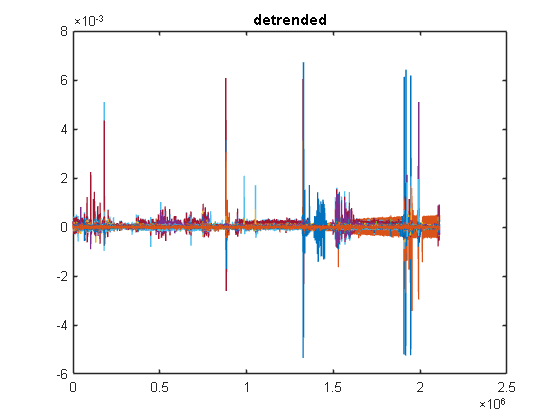

% detrend
ORDER=10; % of polynomial
[x,w]=nt_detrend(x,ORDER);
figure(3); clf
plot(x); title('detrended');

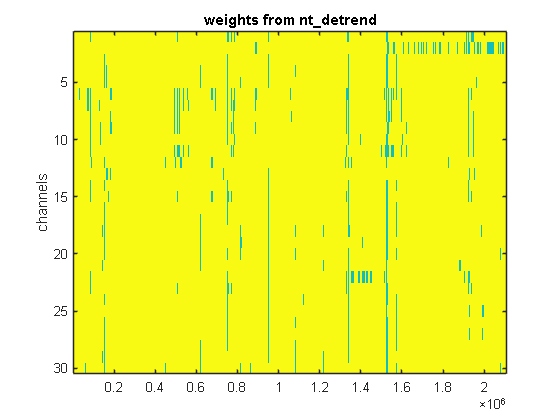

figure(4); clf
nt_imagescc(w'); title('weights from nt_detrend','interpreter','none'); ylabel('channels')

% find outliers, inpaint
if 0 % not needed for these data, time consuming
    
    thresh=2; % threshold for declaring an outlier
    niter=3; % number of iterations
    [w,y]=nt_outliers(x,w,thresh,niter);
    
    
    figure(101); clf;
    nt_imagescc(w'); title('weights from nt_outliers'); ylabel('channels')
    
    if 1
        x=y; % all samples replaced
    else
        y=nt_inpaint(x,w); % interpolate over outliers
        x=y; % only outlier samples replaced
    end
    
    figure(102); clf
    plot([x,y]); legend('raw','outliers interpolated');
end

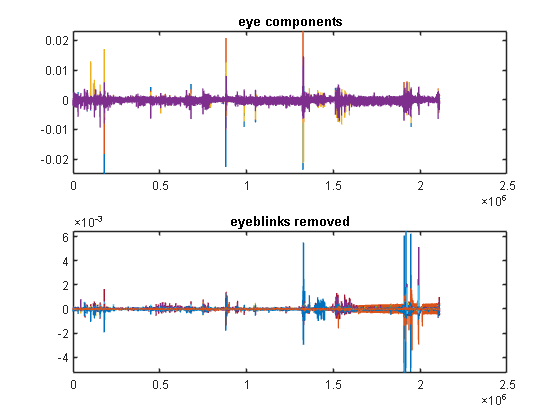

if 1
    % remove eyeblinks
    eye_channels=[6 7 8 9 10 11];
    [B,A]=butter(2,1/(sr/2), 'high');
    tmp=nt_pca(filter(B,A,x(:,eye_channels)));
    mask=abs(tmp(:,1))>3*median(abs(tmp(:,1)));
    C0=nt_cov(x);
    C1=nt_cov(bsxfun(@times, x,mask));
    [todss,pwr0,pwr1]=nt_dss0(C0,C1);
    figure(5); plot(pwr1./pwr0, '.-'); ylabel('score'); xlabel('component'); title ('eyeblink DSS');
    eye_components=x*todss;
    NREMOVE=4; % arbitrary, may need adjusting
    x=nt_tsr(x,eye_components(:,1:NREMOVE));
    figure(6); clf;
    subplot 211; plot(eye_components(:,1:NREMOVE)); title('eye components');
    subplot 212; plot(x); title('eyeblinks removed');
end

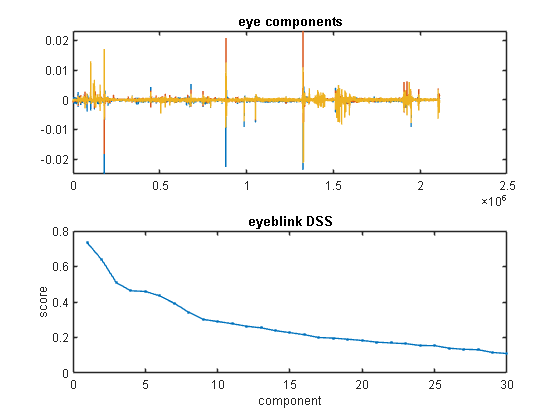

figure(5); plot(pwr1./pwr0, '.-'); ylabel('score'); xlabel('component'); title ('eyeblink DSS');

% rereference
x=nt_rereference(x,w);

plot(mean(eye_components(:,6,:),3))
xlim([1 1000]); % Set the limits of the x-axis
uicontrol('Visible','off')

%save cleaned data "x"

save('dss_eeg_eog_data.mat', 'x', '-v7.3');

% cut into epochs
%idxTrig=find(trigchan(1:end-1)<0.5 & trigchan(2:end)>0.5);
%PRE=round(sr*0.3); % pad to anchor detrending
%POST=round(sr*0.9); 
%nsamples=PRE+POST;
%nchans=size(x,2);
%ntrials=numel(idxTrig);
%xx=zeros(nsamples,nchans,ntrials); 
%for iTrial=6:ntrials-5
%    xx(:,:,iTrial)=x((idxTrig(iTrial)-PRE+1):(idxTrig(iTrial)+POST),:);
%end
%xx=nt_demean(xx);

% remove outlier trials
%THRESH=5;
%iKeep=nt_find_outlier_trials(xx,THRESH);
%xx=xx(:,:,iKeep);
%xx=nt_demean(xx);

% DSS to emphasize repeatablity
%[todss,pwr0,pwr1]=nt_dss1(xx);
%fromdss=pinv(todss);
%z=nt_mmat(xx,todss);

%figure(9); clf;
%subplot 121;
%plot(pwr1./pwr0,'.-'); xlabel('component'); ylabel('score'); title ('repeatability DSS');
%subplot 122;
%nt_bsplot(z(:,1,:)); title('best DSS component');


% denoise by selecting best components and projecting back to sensor space
%NKEEP=7;
%y=nt_mmat(xx,todss(:,1:NKEEP)*fromdss(1:NKEEP,:));

%figure(10); clf;
%subplot 121; plot(mean(xx,3)); title('before DSS denoising');
%subplot 122; plot(mean(y,3)); title('after');

%save cleaned data "yy"

%save('dss_eeg_data.mat', 'y', '-v7.3');